# THE ADORATION OF THE MAGI

## When was the Adoration of the Magi?

The Evangelist Matthew in Chapter II tells us the story of the Magi arriving in Jerusalem on their way to Bethlehem. After their meeting with King Herod the Great, they await the rising of the star that guides them. Then they make the trip to Bethlehem.

In 2011, I attempted to verify this account based on the course of the conjunction of the year 7BC (Jupiter / Saturn - called the Star of Bethlehem by astrophysicists) and the exact course that the Magi had had to browse. This conjunction was visible in the skies of Israel between March 7BC and January 6 BC.

The mathematical model that emerges from this account has proven to be extremely rigid (mathematically speaking) - the only variable of adjustment being the speed of the Magi's caravan. But even there we do not have much room for adjustment. 

Considering this model with rigid parameters, the question is: **Is it possible that this event happened on December 25 of the year 7 BC?**

References:

[1] Marcel Bodor (Thesis 2011). L’Adoration des mages - La Sainte Bible et l’Astronomie. Copyright France© Ref: T7V41B6 ([FR](https://drive.google.com/file/d/0B2t_eiaeU_CqT0RPR29ndElJSUU/view?usp=sharing)) 

[2] Marcel Bodor (Article - 2020). Adoration of the Magi - Where are we 2026 later. ([EN](https://drive.google.com/file/d/1t5UzxrANoYvZMJ9TEneJ9p2EDo3gy8fc/view) - [FR](https://drive.google.com/file/d/1GHSS_VA9vm3VQbiDJp0z3dByDb3pwLRa/view) - [ES](https://drive.google.com/file/d/1SgVNLWlYYlP7lCsPI-Sw85rFr5hJ1EBX/view))

        Videos : 03:24 : [Introduction](https://youtu.be/FwBl2qswqTs) , 07:37 : [Video 1](https://youtu.be/M8J9nbDz1Lk) , 07:36 : [Video 2](https://youtu.be/xuuGJyR1iu0) , Video (fr) : [Présentation](https://www.youtube.com/watch?v=JmlzWFts1hc)

[3] James Evans “The History and Practice of ancient astronomy" Oxford University Press 1998.

Submitted to Vatican Observatory on September 14, 2020.

## Initialization

Loading of Jupiter's ephemeris for the year 7BC:

- Loading Jupiter ephemeris.

- Loading and showing the map of the Jerusalem and Bethlehem area.

- Perform initialization Const/Vars. 

- Check caravan speed validity.

clearvars;close all;clc;
load('AoM.mat');        %- Load ephemeris file (data), map of Jerusalem (map)
                        %- caravan and star (structures)
imshow(map);            %- Display Jerusalem's map

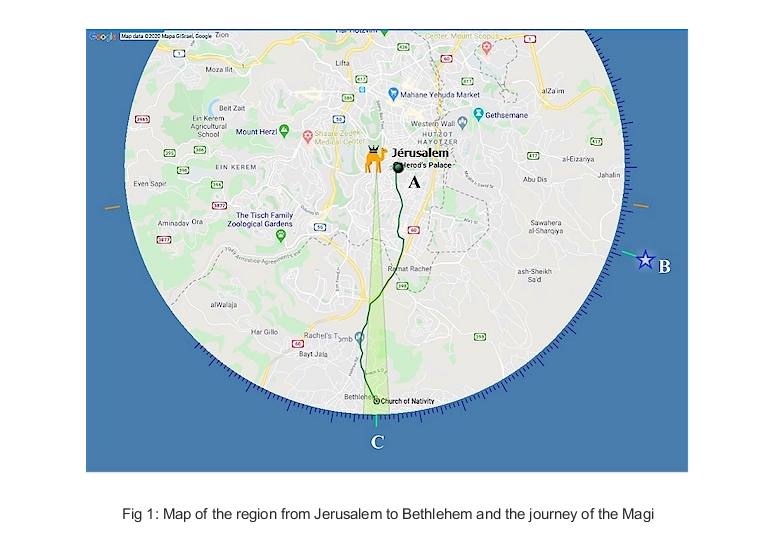

xlabel('Fig 1: Map of the region from Jerusalem to Bethlehem and the journey of the Magi');


%- Constants/Variables
caravan.speed    = 6;   %- km/h From 5-7 Km/h for a camel caravan
caravan.distance = 8.5; %- km   From Herod's Palace to Bethlehem 
                        %- (Church of Nativity)
timespan = 7;           %- Nb of minutes of tolerance to accept 
                        %- or reject a valid event Star + Caravan
                        %- arriving at Bethlehem.

%- Check the caravan speed for validity
if (caravan.speed>7) || (caravan.speed<5)
  msg = "Invalid caravan speed (" + num2str(caravan.speed) +" km/h) !";
  f = msgbox(msg);
  error(msg)     
end

## Extension to all mathematically possible dates.

The only variable in this extremely constrained model is the speed of the Magi caravan.

The time of first visibility of the star varies by 4 minutes per day, so it is mathematically possible that the meeting of the caravan with the star has occurred on other days. This section intends to investigate these other dates, as well as the probability associated with each of them.(*Based on the optimal speed for each possible dates.*)

If we calculate the speed of the caravan to make it correspond to the time of transit of the star, we obtain the following table.

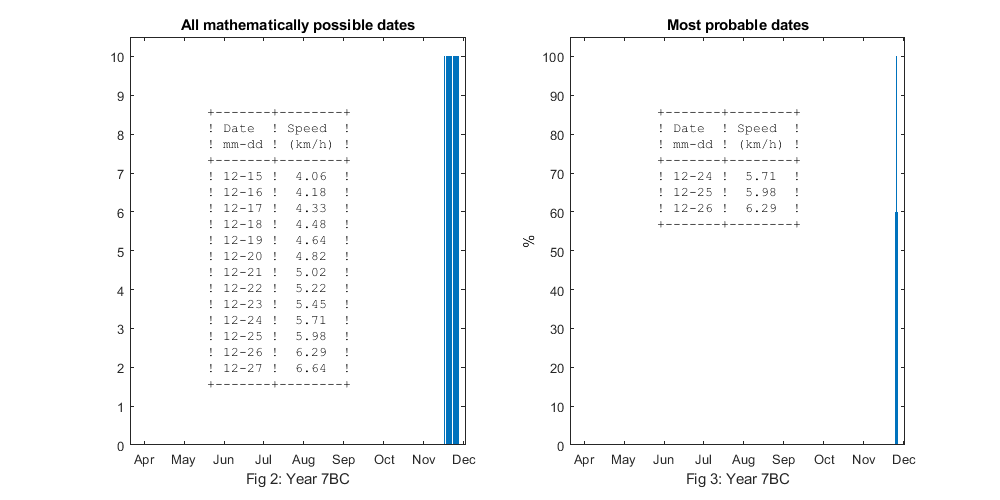

[data] = AoM_MainLoop(data,caravan,star,timespan,false); %- Perform all calculations -> data (without display)
AoM_PosDates(data);                                      %- Graph of mathematically possible/ most probable dates

## Simulation for a caravan at 6 km/h (Most likely speed) 

A camel caravan maybe of different type :

- In progress, a caravan averaged 2–3 miles (3–5 km) per hour for 8 to 14 hours each day or, in hot weather, each night.  (ref. : [https://www.britannica.com/topic/caravan-desert-transport)](https://www.britannica.com/topic/caravan-desert-transport)). In hot weather, on a long journey, a camel characteristically carried  about 350 pounds (160 kg); but, on shorter journeys, in cooler weather,  or in order to evade customs duties, the animal’s load might be  increased to 1,000 pounds. 

- A lightly loaded travel caravan without a "walker" in front of the camels, moves slightly faster (5-7 km/h)

We will therefore take option number (**2**). Taking the average: **6 km/h**

% SIMULATION FOR A CARAVAN AT 6 km/h 
[data] = AoM_MainLoop(data,caravan,star,timespan,true);%- Perform all calculations -> data (with display)

Simulation :
------------

Caravan speed ..... : 6.00 Km/h
Distance to travel  : 8.50 Km
Time span tolerance : 7 min.

Possible dates : 

  Date (mm-dd-yy)... : 12-24-07 BC
  Caravan arrive at  : 16:52
  Star transit at .. : 16:57
  Difference ....... :  4 min.
  Caravan speed .... : 5.71 km/h

  Date (mm-dd-yy)... : 12-25-07 BC
  Caravan arrive at  : 16:53
  Star transit at .. : 16:53
  Difference ....... :  0 min. <- Match
  Caravan speed .... : 5.98 km/h

  Date (mm-dd-yy)... : 12-26-07 BC
  Caravan arrive at  : 16:54
  Star transit at .. : 16:50
  Difference ....... : -4 min.
  Caravan speed .... : 6.29 km/h



## Plot the general map and the results for a caravan at 6 km/h (Normal speed) 

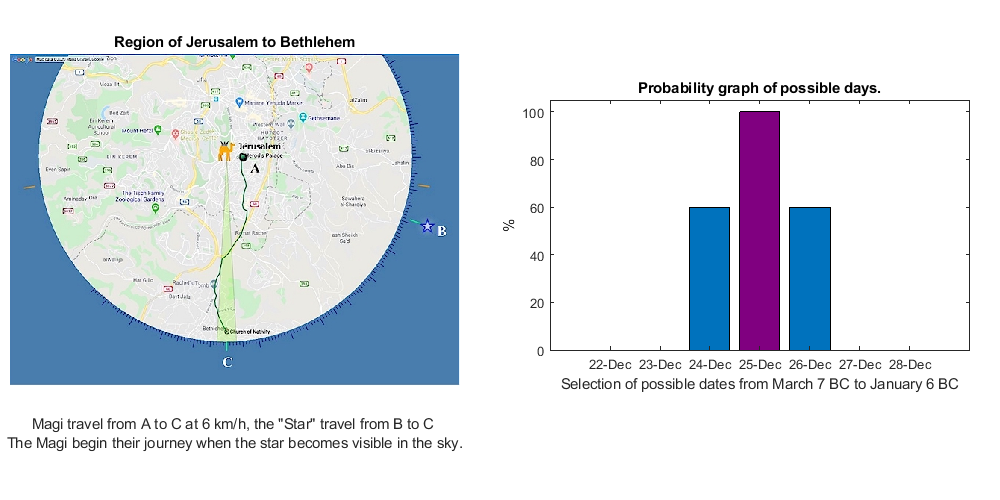

[data] = AoM_At6(data,caravan,map);

This mathematical model based on the account of Matthew the Evangelist and on planetology gives us a surprising result. Moreover, it is corroborated by other factual elements such as geopolitics at the time of Jesus, history, the possible route of the three wise men, the first date of appearance of the star etc ... I do not enter here in these considerations. However, if you are interested in the topic you can read the 2020 article which will give you a good overview of these arguments. ( [(EN) The Adoration of the Magi ](https://drive.google.com/file/d/1t5UzxrANoYvZMJ9TEneJ9p2EDo3gy8fc/view) )

## Conclusion...

We find that even leaving the maximum latitude on the speed of the caravan we get a date that is well within the zone of December 25, year 7 BC. (See Fig 2 and 3)

However, if we choose a value more compatible with the speed of a normally loaded travel trailer, we obtain a date extremely close to December 25 (Julian Calendar).

 I think that this mathematical model clearly shows the correlation between the historical facts as related in Matthew chapter II and the planetology data related to the conjunction of the year 7BC. And allow us to conclude that the date of December 25 may be linked to the account of Matthew the Evangelist.